# Example 6.15: System Identification for CO2

Note: this script reproduces Example 6.15 (Section 6.3.3) of **Statistics for Chemical Engineers**: estimating a dynamic model from the spectra of the input and output signals. Victor Z UW-Madison, 2024 system identification example

clc; clear all; close all hidden;

## Data

load data

load 'Data/data_sysid_co2.dat';
t = data_sysid_co2(:,1);
u = data_sysid_co2(:,2);
x = data_sysid_co2(:,3);
L = length(t);
T = (t(2)-t(1));

% adjust using reference of 400 ppm
x = x-400;

## Empirical spectra and amplitude ratio

get empirical spectrum of u

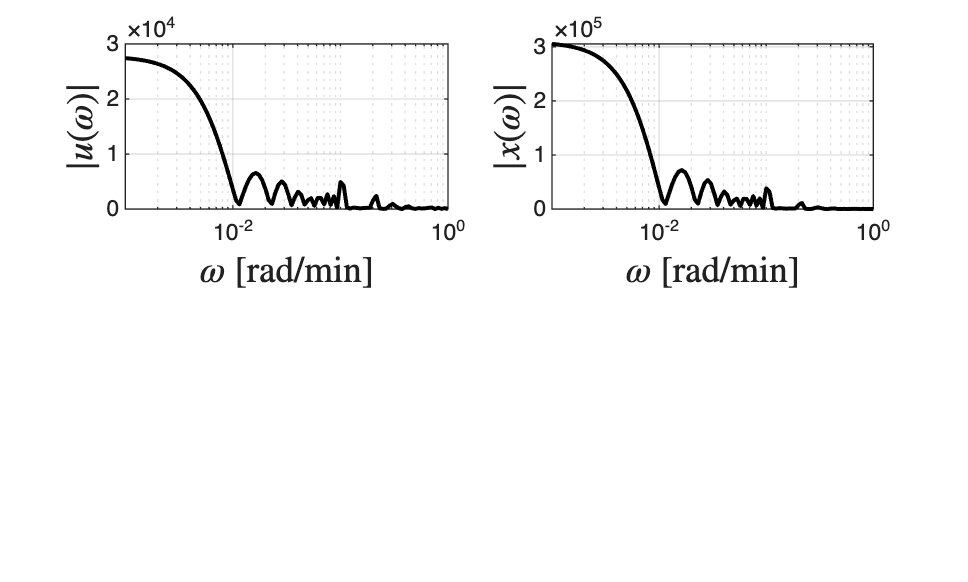

om = logspace(-3,0,100); % frequency range (rad/s)

for k=1:length(om)
    sum1 = u.*cos(om(k)*t);
   B1(k) = trapz(sum1);
    sum2 = u.*sin(om(k)*t);
   B2(k) = trapz(sum2);   
 magu(k) = sqrt(B1(k)^2 + B2(k)^2); 
end

% get empirical spectrum of x
for k=1:length(om)
    sum1 = x.*cos(om(k)*t);
   A1(k) = trapz(sum1);
    sum2 = x.*sin(om(k)*t);
   A2(k) = trapz(sum2);   
 magx(k) = sqrt(A1(k)^2 + A2(k)^2); 
end

% visualize spectrum
figure(2)
subplot(2,2,1)
semilogx(om,magu,'black-','LineWidth',1.5)
hold on
xlabel('$\omega$ [rad/min]','Interpreter','latex','FontSize',14)
ylabel('$|u(\omega)|$','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,2)
semilogx(om,magx,'black-','LineWidth',1.5)
hold on
xlabel('$\omega$ [rad/min]','Interpreter','latex','FontSize',14)
ylabel('$|x(\omega)|$','Interpreter','latex','FontSize',14)
grid on


% get empirical amplitude ratio
AR = magx./magu;

## Estimation

formulate estimation problem

th=[1,1];
thlb=[0,0];
thub=[100,100];
data.AR=AR;
data.om=om;

options = optimoptions(@lsqnonlin,'Display','iter','MaxFunctionEvaluations',5000);
[thhat,~,~,~,~,~,J] = lsqnonlin(@lsfun,th,thlb,thub,options,data);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3           6645.36                         7.28e+04
     1          6           515.794         2.56112         1.18e+04      
     2          9           29.7093        0.482401              974      
     3         12           4.05767        0.216816              113      
     4         15           3.63877       0.0369299             4.01      
     5         18           3.63822      0.00136835            0.068      
     6         21           3.63822     2.42128e-05          0.00114      

Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<<


thhat

thhat =    11.1053    9.9220


## Comparison (Bode plot)

compare model and empirical spectrum

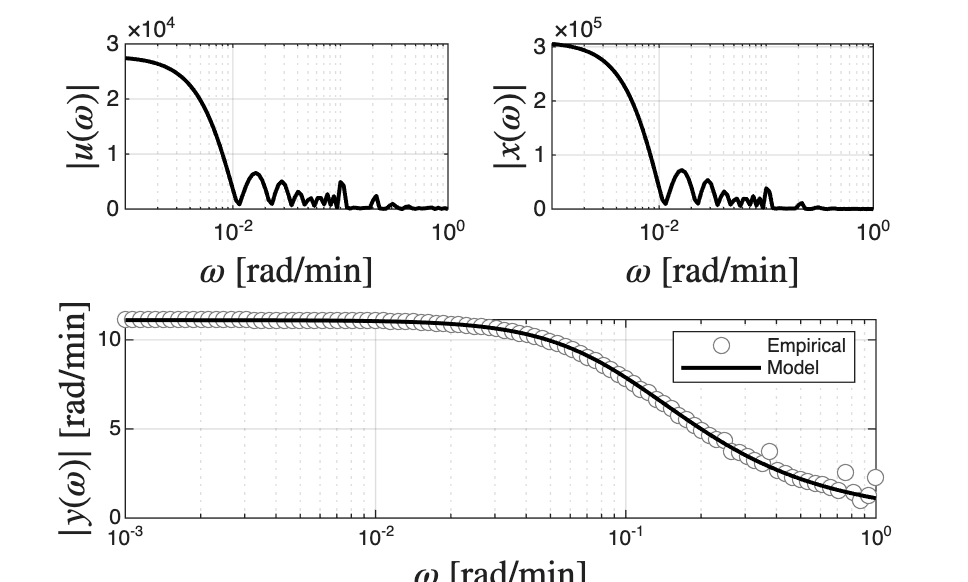

K=thhat(1);
tau=thhat(2);
ARhat=K./sqrt((tau*om).^2+1);

subplot(2,2,[3 4])
semilogx(om,AR,'o','MarkerFaceColor','w','Color',[0.5 0.5 0.5])
hold on
semilogx(om,ARhat,'black-','LineWidth',1.5)
xlabel('$\omega$ [rad/min]','Interpreter','latex','FontSize',14)
ylabel('$|y(\omega)|$ [rad/min]','Interpreter','latex','FontSize',14)
grid on
legend('Empirical','Model')
print -depsc ch6_sysid_results.eps


% back calculate parameters 
   V = 10000;        %  cf  (building volume)
   Q = V/tau

Q = 1.0079e+03

   G = K*Q

G = 1.1193e+04

## verify using Matlab built-in functons

% create data object using x(t),u(t)
 data = iddata(x,u,T);
 
% identify system (fit it to 1st-order system)
sys_estimated = procest(data,'P1') 

sys_estimated = Process model with transfer function:
             Kp                      
  G(s) = ----------                  
          1+Tp1*s                    
                                     
        Kp = 11.12                   
       Tp1 = 10.109                  
                                     
Parameterization:
    {'P1'}
   Number of free coefficients: 2
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 99.83%                     
FPE: 0.2426, MSE: 0.242                            
 
Model Properties

## define residual function

function F=lsfun(th,data)

AR=data.AR;
om=data.om;
K=th(1);
tau=th(2);
ARhat=K./sqrt((tau*om).^2+1);

F=AR-ARhat;

end
 

## Note

As in the book, the amplitude ratio of the model matches the empirical one; this Bode plot is widely used in system identification and control.